# SPS Atlas

## Load *D.melanogaster* genome

clear all; close all; clc;
% dmel = {};
% dmel.X = getgenbank('NC_004354','SequenceOnly',true);
% %dmel.Y = getgenbank('NC_024512','SequenceOnly',true);
% dmel.twoL = getgenbank('NT_033779','SequenceOnly',true);
% dmel.twoR = getgenbank('NT_033778','SequenceOnly',true);
% dmel.threeL = getgenbank('NT_037436','SequenceOnly',true);
% dmel.threeR = getgenbank('NT_033777','SequenceOnly',true);
% dmel.four = getgenbank('NC_024512','SequenceOnly',true);


## D.mel Split Load

FileName = 'GCF_000001215.4_Release_6_plus_ISO1_MT_genomic (1).fna';
Seq = fastaread(FileName);
for j = 1:length(Seq)
   MMName = sprintf('DmelSeq_%d.mm', j);
   FID = fopen(fullfile('C:\Users\che7oz\Documents\GitHub\FASTA\dmel', MMName), 'w');
   intData = nt2int(Seq(j).Sequence);
   fwrite(FID,intData,'uint8');
   fclose(FID);
end

## Load *D.simulans* genome

% dsim = {};
% dsim.X = getgenbank('NC_029795','SequenceOnly',true);
% dsim.twoL = getgenbank('NT_479533','SequenceOnly',true);
% dsim.twoR = getgenbank('NT_479534','SequenceOnly',true);
% dsim.threeL = getgenbank('NT_479535','SequenceOnly',true);
% dsim.threeR = getgenbank('NT_479536','SequenceOnly',true);
% dsim.four = getgenbank('NC_029796','SequenceOnly',true);

## D.sim Split Load

FileName = 'GCF_000754195.2_ASM75419v2_genomic.fna';
Seq = fastaread(FileName);
for j = 1:length(Seq)
   MMName = sprintf('DsimSeq_%d.mm', j);
   FID = fopen(fullfile('C:\Users\che7oz\Documents\GitHub\FASTA\dsim', MMName), 'w');
   intData = nt2int(Seq(j).Sequence);
   fwrite(FID,intData,'uint8');
   fclose(FID);
end


## Load *D.yakuba* genome

% dyak = {};
% dyak.X = getgenbank('NC_011091','SequenceOnly',true);
% dyak.twoL = getgenbank('NT_167062','SequenceOnly',true);
% dyak.twoR = getgenbank('NT_167063','SequenceOnly',true);
% dyak.threeL = getgenbank('NT_167064','SequenceOnly',true);
% dyak.threeR = getgenbank('NT_167065','SequenceOnly',true);
% dyak.four = getgenbank('NC_011090','SequenceOnly',true);

## D.yakuba Split Load

FileName = 'GCF_000005975.2_dyak_caf1_genomic.fna';
Seq = fastaread(FileName);
for j = 1:length(Seq)
   MMName = sprintf('DyakSeq_%d.mm', j);
   FID = fopen(fullfile('C:\Users\che7oz\Documents\GitHub\FASTA\dyak', MMName), 'w');
   intData = nt2int(Seq(j).Sequence);
   fwrite(FID,intData,'uint8');
   fclose(FID);
end

## Load SPS half-Motifs fwd

%ref SpDamID paper (Fig. 7)
SPS.a = char('GGCTGGGGG');
SPS.b = char('CAGGTGGGAA');
SPS.c = char('TAAAAGGGG');
SPS.d = char('AGGATGAGT');
SPS.e = char('AGGCCTGGC');

## Load SPS half-Motifs rev

SPS.f = seqrcomplement(SPS.a);
SPS.g = seqrcomplement(SPS.b);
SPS.h = seqrcomplement(SPS.c);
SPS.i = seqrcomplement(SPS.d);
SPS.j = seqrcomplement(SPS.e);

## Load SPS Consensus - Kopan, R. SpDamID paper

SPS.r = char('BVYGDGAD');
SPS.s = seqrcomplement(SPS.r);

## Search Alg Brute

% k1 = strfind(dmel.X, SPS.a)
% k2 = strfind(dmel.X, SPS.b)
% k3 = strfind(dmel.X, SPS.c)
% k4 = strfind(dmel.X, SPS.d)
% k5 = strfind(dmel.X, SPS.e)
% 
% k6 = strfind(dmel.X, SPS.f)
% k7 = strfind(dmel.X, SPS.g)
% k8 = strfind(dmel.X, SPS.h)
% k9 = strfind(dmel.X, SPS.i)
% k10 = strfind(dmel.X, SPS.j)


## Search Alg Iterative

Sfields = fieldnames(SPS);
Dfields = fieldnames(dmel);
for i = 1:length(fieldnames(SPS));
    for j = 1:length(fieldnames(dmel))
        qq{:,1,j,i} = strfind(dmel.(Dfields{j}), SPS.(Sfields{i}))';
    end
end

% n = 2;
% fields = fieldnames(struc);
% struc.(fields{n})

## Group by Chromosome

ra = [];
rb = [];
rc = [];
rd = [];
re = [];
rf = [];

for i = 1:length(fieldnames(SPS));
    ra = [ra; qq{:,1,1,i}]; %dmel.X
    rb = [rb; qq{:,1,2,i}]; %dmel.twoL
    rc = [rc; qq{:,1,3,i}]; %dmel.twoR
    rd = [rd; qq{:,1,4,i}]; %dmel.threeL
    re = [re; qq{:,1,5,i}]; %dmel.threeR
    rf = [rf; qq{:,1,6,i}]; %dmel.four
end

rtot = length(ra) + length(rb) + length(rc) + length(rd) + length(re) + length(rf)

rtot = 3774

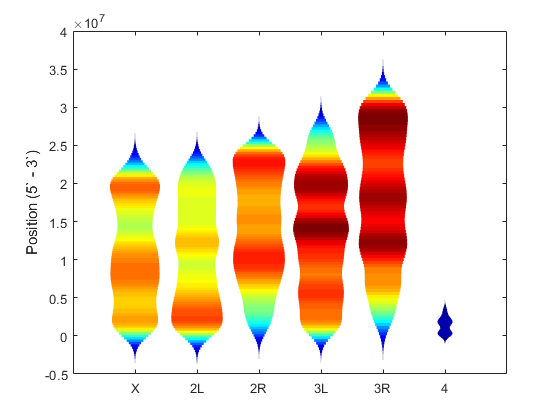


rad = ra/length(dmel.X);
rbd = rb/length(dmel.twoL);
rcd = rc/length(dmel.twoR);
rdd = rd/length(dmel.threeL);
red = re/length(dmel.threeR);
rfd = rf/length(dmel.four);

% figure, 
% scatter(ones(length(ra),1), rad, '.'); hold on;
% scatter(ones(length(rb),1)*2, rbd, '.');
% scatter(ones(length(rc),1)*3, rcd, '.');
% scatter(ones(length(rd),1)*4, rdd, '.');
% scatter(ones(length(re),1)*5, red, '.');
% scatter(ones(length(rf),1)*6, rfd, '.');
% xlim([0 7]);
% box on;


rall = {ra, rb, rc, rd, re, rf};
rnames = {'X', '2L', '2R', '3L', '3R', '4'};
figure,
distributionPlot(rall, 'showMM', 0, 'colormap', jet, 'globalNorm', 2, 'xNames', rnames); 
box on;
ylabel('Position (5` - 3`)')

## Group by Motif (Needs Work)

sa = [];
sb = [];
sc = [];
sd = [];
se = [];

sf = [];
sg = [];
sh = [];
si = [];
sj = [];

for i = 1:length(fieldnames(dmel));
    sa = [sa; qq{:,1,i,1}]; %SPS.a
    sb = [sb; qq{:,1,i,2}]; %SPS.b
    sc = [sc; qq{:,1,i,3}]; %SPS.c
    sd = [sd; qq{:,1,i,4}]; %SPS.d
    se = [se; qq{:,1,i,5}]; %SPS.e
    
    sf = [sf; qq{:,1,i,6}]; %SPS.f
    sg = [sg; qq{:,1,i,7}]; %SPS.g
    sh = [sh; qq{:,1,i,8}]; %SPS.h
    si = [si; qq{:,1,i,9}]; %SPS.i
    sj = [sj; qq{:,1,i,10}]; %SPS.j
end

stot = length(sa) + length(sb) + length(sc) + length(sd) + length(se) + length(sf) + length(sg) + length(sh) + length(si) + length(sj)

stot = 3774

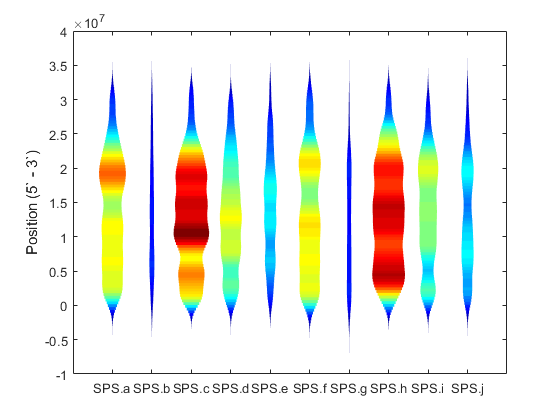


sad = sa/length(SPS.a);
sbd = sb/length(SPS.b);
scd = sc/length(SPS.c);
sdd = sd/length(SPS.d);
sed = se/length(SPS.e);

sfd = sf/length(SPS.f);
sgd = sg/length(SPS.g);
shd = sh/length(SPS.h);
sid = si/length(SPS.i);
sjd = sj/length(SPS.j);

sall = {sa, sb, sc, sd, se, sf, sg, sh, si, sj};
snames = {'SPS.a', 'SPS.b', 'SPS.c', 'SPS.d', 'SPS.e', 'SPS.f', 'SPS.g', 'SPS.h', 'SPS.i', 'SPS.j', };
figure,
distributionPlot(sall, 'showMM', 0, 'colormap', jet, 'globalNorm', 2, 'xNames', snames); 
box on;
ylabel('Position (5` - 3`)')


%Maybe sort by Chromosome as well

## Alignment

AlignStruct = localalign(dmel.threeR, SPS.s, 'Alphabet', 'NT');
AlignStruct.Alignment{1}

ans = 3×7 char array
    'TCCCTTC'
    '|| | ||'
    'TCHCHTC'


## SPS Location Store

% dmelSPS = {}
% dmelSPS.X = {k1, k2, k3, k4, k5}

## Load *D.sechellia* genome

% dsec = {};
% FASTAfilename = 'GCF_000005215.3_dsec_caf1_genomic.fa';
% fileInfo = dir(which(FASTAfilename))
% fidIn = fopen(FASTAfilename,'r');
% header = fgetl(fidIn)
% [fullPath, filename, extension] = fileparts(FASTAfilename);
% mmFilename = [filename '.mm']
% fidOut = fopen(mmFilename,'w');
% newLine = sprintf('\n');
% blockSize = 2^12;
% while ~feof(fidIn)
%     %Read in the data
%     charData = fread(fidIn,blockSize,'*char')';
%     %Remove new lines
%     charData = strrep(charData,newLine,'');
%     %Convert to integers
%     intData = nt2int(charData);
%     %Write to the new file
%     fwrite(fidOut,charData,'uint8');
% end
% fclose(fidIn);
% fclose(fidOut);
% mmfileInfo = dir(mmFilename)
% chr1 = memmapfile(mmFilename, 'format', 'uint8')

FileName = 'GCF_000005215.3_dsec_caf1_genomic.fa';
Seq = fastaread(FileName);
for j = 1:length(Seq)
   MMName = sprintf('DsecSeq_%d.mm', j);
   FID = fopen(fullfile('C:\Users\che7oz\Documents\GitHub\FASTA\dsec', MMName), 'w');
   intData = nt2int(Seq(j).Sequence);
   fwrite(FID,intData,'uint8');
   fclose(FID);
end


## Load D.erecta genome

% dere = {};

## Load D.anasai genome

% dana = {};

## Load D.pseudoobscura genome

% dpse = {};

## Load D.persimilis genome

% dper = {};

## Load D.**willistoni** genome

% dwil = {};

## Load D.mojavensis genome

% dmoj = {};

## Load D.virilis genome

% dvir = {};